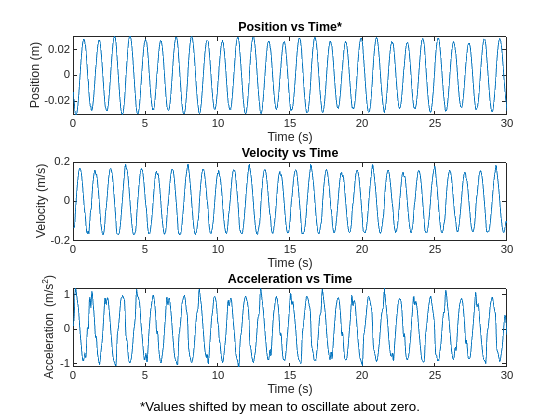

% Kym Derriman (Partner: Evan Howell)
% Lab 6: Damped Harmonic Motion
% 10/17/2024

% --------------------------------------------
% Spring Force vs Displacement Analysis (500g)
% --------------------------------------------

% Data from oscillating spring with 500g weight attached.
tbl = readtable("L6_500g_Oscillation.txt");
times = tbl.Time;
positions = tbl.Position;
velocities = tbl.Velocity;
accelerations = tbl.Acceleration;

% Invert the positions to make show positive displacement
shifted_pos = positions - mean(positions); 

% --------------------------------------------------
% Plot Displacement, Velocity, Acceleration Data
% --------------------------------------------------

% Subplots for Position, Velocity, Acceleration
figure;

subplot(3, 1, 1); plot(times, shifted_pos);
title('Position vs Time*'); xlabel('Time (s)'); ylabel('Position (m)');

subplot(3, 1, 2); plot(times, velocities);
title('Velocity vs Time'); xlabel('Time (s)'); ylabel('Velocity (m/s)');

subplot(3, 1, 3); plot(times, accelerations);
title('Acceleration vs Time'); xlabel('Time (s)'); ylabel('Acceleration (m/s^2)');

% Add annotation to indicate the asterisk explanation
annotation('textbox', [0.1, 0.01, 0.8, 0.05], 'String', ...
    '*Values shifted by mean to oscillate about zero.','EdgeColor', 'none', ...
    'HorizontalAlignment', 'center', 'FontSize', 10);